# Relatório de Atividade - Controle Adaptativo

*Débora Nunes Pinto de Oliveira*

*Prof. Antonio Marcus, Análise e Projeto de Sistemas de Controle 21.1*

*19 de abril de 2021*

Esse documento tem por objetivo descrever a implementação de estratégias de controle adaptativo. Esse algoritmo determina uma lei de controle não-linear, cujos parâmetros devem ser atualizados para obedecer a critérios de performance pré-definidos. O controle adaptativo é adequado para processos não-lineares ou variantes no tempo. 

## Fundamentação Teórica

    Com o intuito de rejeitar variações inerentes ao processo, o controlador de uma planta é construído a partir de um laço de realimentação. Conforme o número de polos e zero do processo controlado, a estratégia de controle construída com ação proporcional, derivativa e/ou integral é capaz de garantir a performance do sistema segundo critérios pré-definidos (e.g. *overshoot*, tempo de acomodação e tempo de subida). 

    Considerando a função de transferência de realimentação $$G_{fb}$$ e a função de transferência *feedfoward *$G_{ff}
$, o sistema pode ser representado conforme no diagrama da Fig. 1. A saída do sistema é nomeada $y$, enquanto a entrada de referência é denominada $u_c$. A relação entre a saída e a entrada é representada pela função de transferência $T$:


$$T = \frac{G_pG_{fb}}{1+G_pG_{fb}} $$


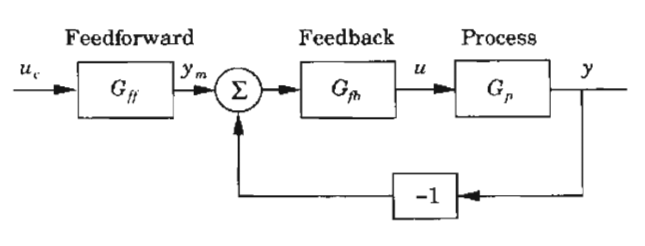

**Figura 1: **Diagrama de blocos de um sistema em malha fechada [1]** . **

    para função de transferência do processo $G_p
$. Derivando $T$ em relação a função de transferência do processo $G_p
$, obtém -se:


$$\frac{dT}{T} = \frac{1}{1+G_pG_{fb}}\frac{dG_p}{G_p} $$


    Logo, é evidente que a função de transferência $T$ é insensível à variações do processo $G_p$ caso o termo $$G_pG_{fb}$$ seja suficientemente grande para as frequências nas quais a planta não é constante. Dessa forma, o controlador $$G_{fb}$$ deve garantir a rejeição dessa variação, apenas nas frequências em que $$G_pG_{fb}\approx 1$$ [1].

    Entretanto, essa estratégia de controle é adequada apenas para perturbações lineares. Para perturbações não-lineares, esse sistema pode discordar dos critérios em regime permanente para alguma das condições de operação. Uma solução apropriada é alterar a função $$G_{fb}$$ conforme a mudança da condição de operação da planta. Essa técnica é chamada escalonamento de ganho (*gain scheduling* $-$GS).

    O diagrama de blocos para o GS está apresentado na Fig. 2. Nessa técnica, há dois laços de controle: um laço interno composto pelo processo e controlador e um laço externo de atualização de parâmetros do controlador conforme a saída da planta. 

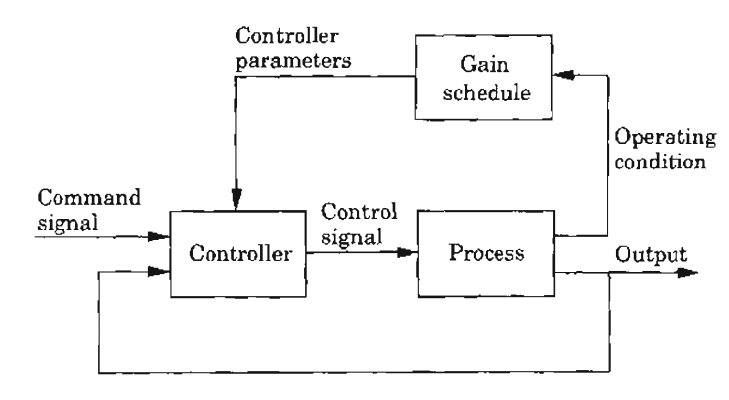

**Figura 2: **Diagrama de blocos de um sistema com GS [1]** . **

   A atualização do controlador é comumente realizada por meio de uma função ou tabela pré-definidas (*look-up table*). Para identificar o ponto de operação da planta, é necessário o conhecimento prévio do modelo da variação do processo. Caso essa perturbação seja irregular, não é possível definir as condições de operação. Nessa situação, é necessário adotar uma estratégia de controle adaptativo. 

    Um exemplo de controlador adaptativo é um sistema de com modelo de referência adaptativo (*model-reference adaptive system* $-$ MRAS). Nessa abordagem, os critérios de performance do sistema são especificados em termos de um modelo de referência do processo. Assim como no GS, o diagrama de bloco para o MRAS desenhado na Fig. 3 possui dois laços de operação: um laço interno composto pelo processo e controlador  e um laço externo de atualização de parâmetros do controlador conforme o modelo de referência. Esse ajuste é realizado segundo os critérios de performance definidos pelo gabarito de referência.

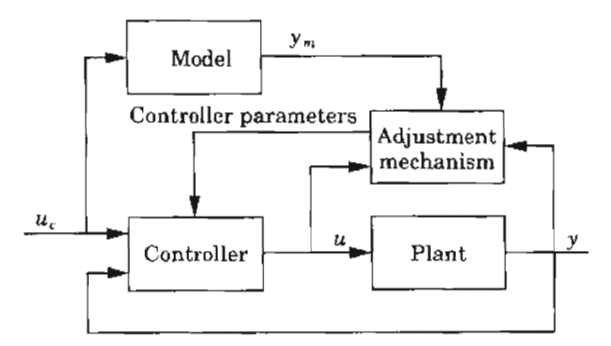

**Figura 3: **Diagrama de blocos de um sistema com MRAS [1]** . **

    Desde que o processo seja mantido constante, o MRAS é capaz de garantir a estabilidade do sistema. Contudo, o modelo do laço externo deve ser estimado caso a planta seja desconhecida. Essa atualização conjunta dos parâmetros do controlador e do modelo de referência é nomeada controlador autorregulável (*self-tuning regulator* $-$STR). O diagrama de blocos dessa técnica está ilustrado na  Fig. 4. No STR, o laço externo incluí a tanto estimativa do modelo do processo, quanto a atualização dos parâmetros do controlador.

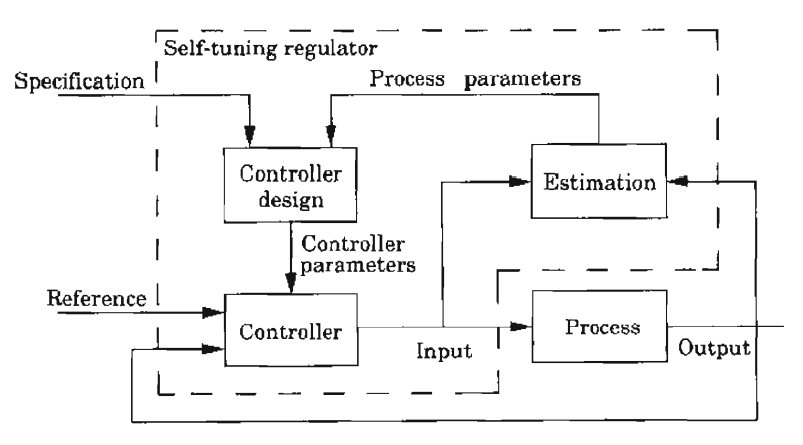

**Figura 4: **Diagrama de blocos de um sistema com STR [1]** . **

    A técnica do STR considera o princípio da equivalência da certeza, isto é, que os estados estimados do processo são equivalentes ao processo real. Portanto, não é considerado a incerteza dos parâmetros do estimador. Essa observação pode ser corrigida a partir de uma abordagem estocástica. Considerando $$x^T$$ e $$\theta^T$
$ os estados de um processo e os parâmetros do controlador, respectivamente, é possível compor o vetor:


$$z = \Big(x^T\;\theta^T\Big)^T

$$


Logo, objetivo do controlador estocástico é minimizar a função de custo:


$$$$V = E\bigg(G(z(T),u(T))+\int_{T}^{0}g(z,u)dt\bigg)$$
$$


para $E$ o valor esperado, $G$ e $g\;$funções escalares de $z$ e $u$ e $T$ o período de amostragem do controlador. Dessa forma, é evidente que essa estratégia requer maior custo computacional que MRAS e STR, uma vez que $V$ dependente de $z$ deve ser atualizada a cada passo de cálculo.

Tendo em vista as técnicas de controle acima propostas, este documento objetiva descrever a reprodução dos exercícios resolvidos e resolução dos exercícios propostos do Capítulo 1 de [1]. 

## Desenvolvimento

Os controladores propostos foram construídos e simulados utilizando blocos no Simulink. As estratégias adotadas seguem a apresentação citada na Seção 1. Primeiramente, serão apresentados os exercícios resolvidos. Por fim, serão discutidas as questões propostas.

### Exercícios resolvidos

#### Exemplo 1: Respostas de malha aberta diferentes

Essa questão tem por objetivo analisar as consequências em malha fechada da estabilidade do processo em malha aberta. Para tal, foram realizados três experimentos considerando a função de transferência:


$$G_0(s) = \frac{1}{(s+1)(s+a)}$$


para $a=-0.01$, $0$ e $0\ldotp 01$. A malha foi fechada utilizando uma lei de controle proporcional para $u=u_c -y$. 

As respostas para a malha aberta no domínio do tempo e frequência e o diagrama de bode para a malha fechada estão ilustrados na Fig. 5:

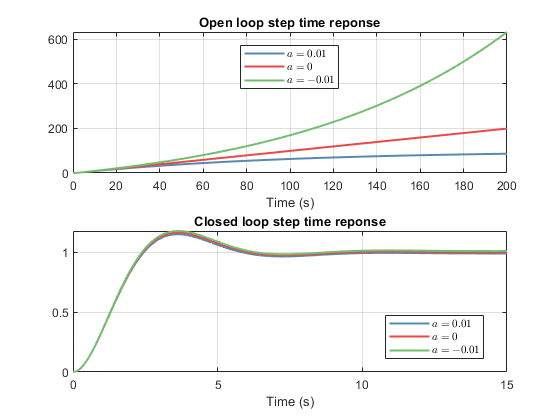

out = sim('Simulink\simulink_ex1.slx');
plot_ex1_time

**Figura 5: **Resposta da malha aberta (acima) e em malha fechada (abaixo) para a função de transferência $G_0,\forall a\in \{-0.01,0, 0.01\}$**. **

Observando a Fig. 5, é evidente que o sistema em malha aberta é estável apenas para $G_0

$ com polo negativo, isto é, $a = 0.01
$. Entretanto, o ganho do controlador proporcional consegue deslocar os polos e estabilizar a malha fechada. Nas Fig. 6 e  Fig. 7 estão ilustrados os diagramas de Bode para a malha aberta e fechada para os diferentes valores de $a$.

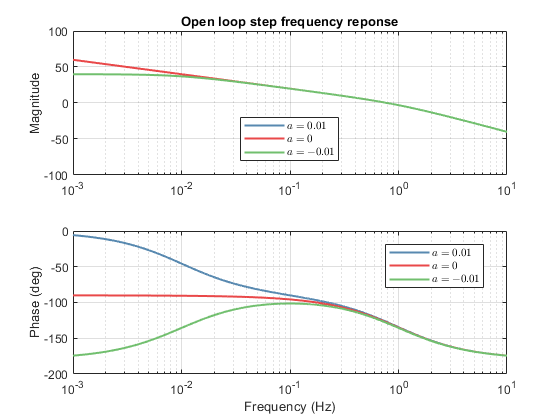

plot_ex1_OL

 **Figura 6: **Diagrama de Bode de malha aberta para a função de transferência $G_0,\forall a\in \{-0.01,0, 0.01\}$**. **

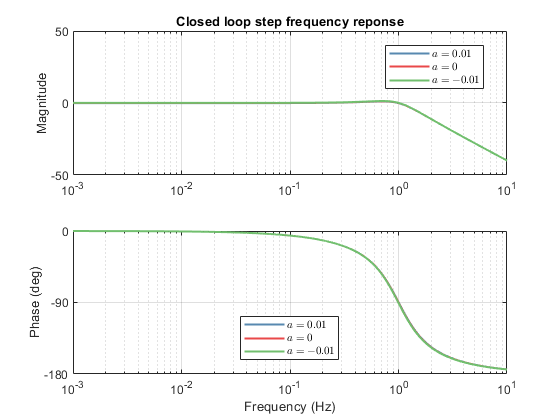

plot_ex1_CL

 **Figura 7: **Diagrama de Bode de malha fechada para a função de transferência $G_0,\forall a\in \{-0.01,0, 0.01\}$**. **

Observando a Fig. 6, é evidente que os sistemas em malha aberta possuem comportamentos idênticos para as altas frequências. Dessa forma, é possível garantir a estabilidade de todos os sistemas em malha fechada para um mesmo controlador caso a largura de banda da lei de controle seja suficientemente alta. A largura de banda da malha é definida como a frequência em que a magnitude da função de transferência em malha fechada é $-3dB$ do ganho DC, ou seja, 0Hz. Observando a Fig. 7, a largura de banda de malha fechada é aproximadamente $1,2$kHz. Essa frequência está localizada sobre o intervalo de comportamentos idênticos para as altas frequências.

Logo, para o mesmo controlador, o comportamento será equivalente e estável para todos os sistemas em malha fechada, conforme ilustrado na resposta temporal em malha fechada na Fig. 5. É possível concluir que, para o caso apresentado, mudanças em malha aberta não implicam em diferentes comportamentos em malha fechada.

#### Exemplo 2: Respostas de malha aberta semelhantes

Essa questão também tem por objetivo analisar as consequências em malha fechada de variações pequenas no processo em malha aberta. Foram realizados três experimentos considerando a função de transferência:


$$G_0(s) = \frac{400(1-sT)}{(s+1)(s+20)(1+Ts)}$$


para $T=0
$,$0\ldotp 015$ e $0\ldotp 03$. A malha foi fechada utilizando uma lei de controle proporcional para $u=u_c -y$. As respostas para a malha aberta no domínio do tempo e frequência e o diagrama de bode para a malha fechada estão ilustrados na Fig. 8:

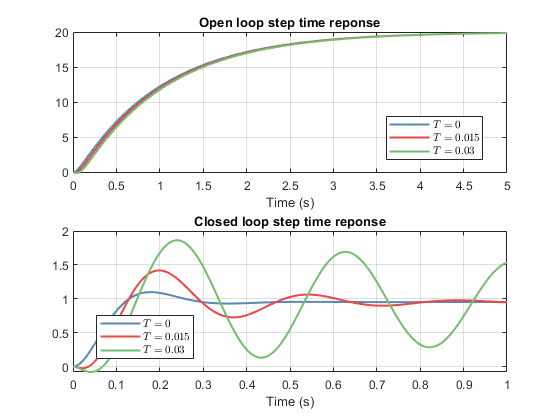

out = sim('Simulink\simulink_ex2.slx');
plot_ex2_time

**Figura 8: **Resposta da malha aberta (acima) e em malha fechada (abaixo) para a função de transferência $G_0,\forall T\in \{0,0.015, 0.03\}$**. **

Observando a Fig. 8, é evidente que o sistema em malha aberta é estável $\forall T\in \{0,0.015, 0.03\}$. Entretanto, o controlador generalizado proporcional produz *overshoot* nos sistemas em malha fechada. Nas Fig. 9 e  Fig. 10 estão ilustrados os diagramas de Bode para a malha aberta e fechada para os diferentes valores de $T$.

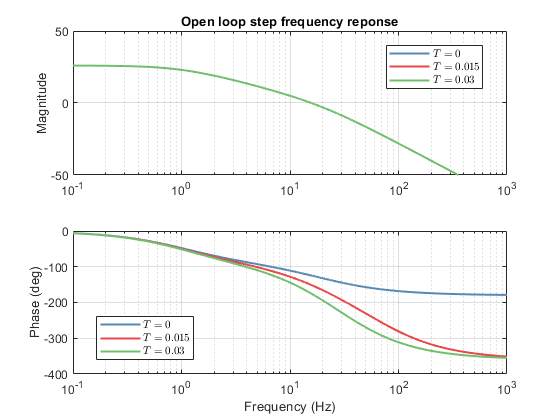

plot_ex2_OL

 **Figura 9: **Diagrama de Bode de malha aberta para a função de transferência $G_0,\forall T\in \{0,0.015, 0.03\}$**. **

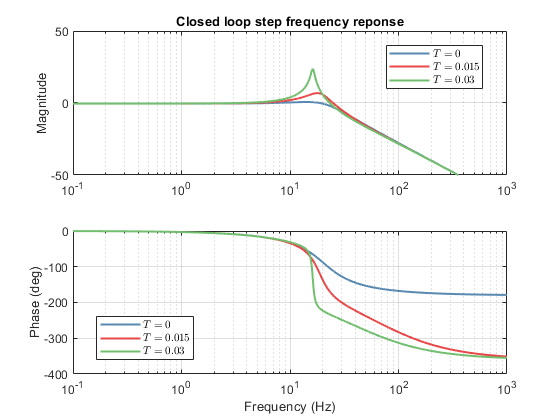

plot_ex2_CL

 **Figura 10: **Diagrama de Bode de malha fechada para a função de transferência $G_0,\forall T\in \{0,0.015, 0.03\}$**. **

    Observando a Fig. 9, é evidente que os sistemas em malha aberta possuem comportamentos idênticos para as baixas frequências. Dessa forma, é possível garantir a estabilidade de todos os sistemas em malha fechada para um mesmo controlador caso a largura de banda da lei de controle seja suficientemente baixa. Observando a Fig. 10, a largura de banda em malha fechada é aproximadamente $25$Hz. Esse valor está fora do intervalo de comportamentos idênticos para as baixas frequências.

  Assim, o comportamento será diferente para os sistemas em malha fechada, conforme ilustrado na resposta temporal em malha fechada na Fig. 8.  É possível concluir que, para o caso apresentado, pequenas mudanças em malha aberta implicam em diferentes comportamentos em malha fechada.

#### Exemplo 3: Integrador com sinal indefinido

O objetivo dessa questão é criar um controlador generalizado para a função de transferência 


$$G_0(s)=\frac{k_p}{s}$$


para $k_p$ valores positivos e negativos. A função $G_{fb}$ do controlador pode ser expressa de modo genérico como $S\left(s\right)/R\left(s\right)$, para $S\left(s\right)$e $R\left(s\right)$ polinômios, tal que o grau de $S\left(s\right)$ é menor ou igual ao grau de $R\left(s\right)$. O polinômio característico de malha fechada pode ser então expresso por:


$$P\left(s\right)=\textrm{sR}\left(s\right)+k_p S\left(s\right)$$


Assumindo $R(s) = s+\alpha$ e $S\left(s\right)=\beta$, obtém-se que $P\left(s\right)=s^2 +\alpha s+k_p \beta$. Logo, os polos da malha fechada são determinados por:


$$p = \frac{-\alpha\pm\sqrt{\alpha^2-4k_p\beta}}{2}$$


Para $k_p >0$, tem-se que $Re(p) < 0$. Porém para $k_p <0$, há pelo menos um polo no semi-plano direito de $s$. Dessa forma, é possível concluir que esse processo não pode ser controlado por uma lei de controle linear racional.  É possível concluir que, para o caso apresentado, é necessário adotar uma estratégia de controle para sistemas não-lineares.

#### Exemplo 4: Válvula não-linear

Esse exercício tem por objetivo construir um controlador para um processo não linear ilustrado na Fig. 11. A função não-linear $f\left(u\right)$ que descreve a válvula é determinada por:


$$v = f(u) = u^4$$


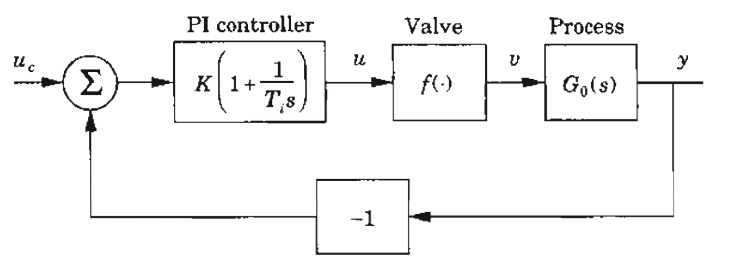

**Figura 11: **Diagrama de blocos de um laço de controle PI e um processo não linear [1]** . **

A não linearidade da válvula implica na oscilação do sistema em malha fechada, uma vez que pequenas magnitudes de $u$ implicarão em grandes valores de $v$ (na ordem de $u^4$). 

A estratégia de controle adequada para garantir a performance adequada do sistema é aplicar a inversão da não-linearidade após a saída do controlador e antes da entrada na planta. Essa estratégia é aplicável por meio da linearização de trechos da função $f\left(u\right)$e pode ser considerada um tipo especial de GS. Na Fig. 12 está ilustrada a linearização da função $f\left(u\right)$ em dois segmentos de reta entre os pontos $x=0$,$1\ldotp 3$ e $2$.

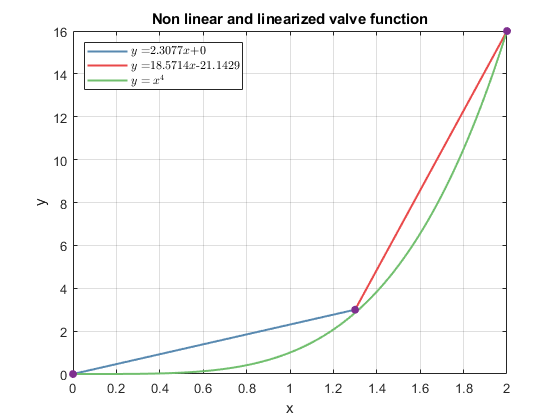

plot_ex4

**Figura 12: **Função não linear da válvula $f\left(u\right)=u^4$ e a aproximação linearizada entre os pares $(x,y) = \{(0,0);(1.3,3);(2,16)\}$**.**

As retas aproximadas para a linearização foram $y=2\ldotp 3077x$ e $y=18\ldotp 5714x-21\ldotp 1429$. Logo, a função  $f^{-1} \left(u\right)$ pode ser definida como 2 segmentos de reta: $x=2\ldotp 3077y$ e $x=18\ldotp 5714y-21\ldotp 1429$. Isolando o termo $y$, obtém-se:


$$f^{-1} (u) = \begin{cases}
0.433u, 0\leq u < 3 \\
0.0538u+1.1385, 3 \leq u <16
\end{cases}$$


Na Fig.13 estão ilustradas a resposta ao degrau no domínio do tempo para a malha fechada com e sem a inversão $f^{-1} \left(u\right)$. Fica evidente que, quando a função não-linear é conhecida, a inversão da mesma na entrada da planta é suficiente para diminuir a oscilação da malha fechada. Essa estratégia não é adequada para modelos de processos desconhecidos. 

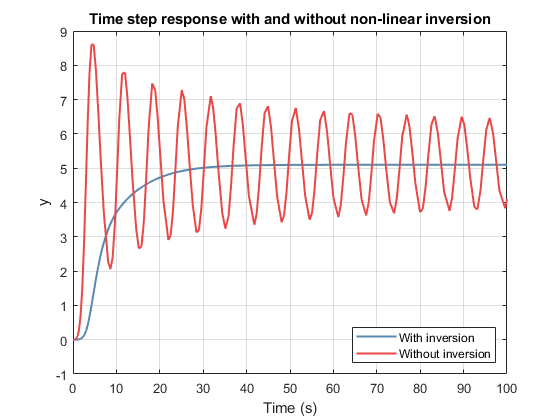

out = sim("Simulink\simulink_ex4.slx");
plot_ex4_simulink

**Figura 13: **Resposta ao degrau para a malha fechada com e sem a inversão da não linearidade da válvula**.**

#### **Exemplo 5:** Controle da concentração de um tanque

Essa questão tem por objetivo projetar um controlador adaptativo para diferentes configurações de um mesmo modelo. Foram realizados quatros experimentos sobre um modelo de tanque, cuja concentração é controlada pelo fluxo do duto de entrada. A concentração e volume do duto de entrada são denominados $c_{in}$ e $V_d$, respectivamente. A concentração e volume do tanque são notados como $c$ e $V_m$, respectivamente. Por fim, o fluxo do duto é representado por $q$. O equacionamento que retrata o balanço de massa desse sistema é:


$$V_m\frac{dc(t)}{dt} = q(t)(c_{in}(t-\tau)-c(t))$$


para $\tau = V_d/q(t)$. Para $q(t)$ constante, tem-se que a função de transferência entre $c_{in}$ e $c$ é:


$$G_0(s) = \frac{e^{s\tau}}{1+sT}$$


para $T = V_m/q(t)$. Considerando $T=1$, $\tau=1$ e $q\in \{0.5;1.0,2.0\}$, pode-se esboçar as respostas ao degrau unitário para um controlador PI constante ($$K_p=0.5$$ e $T_i=1.1$), conforme ilustrado na Fig. 14. 

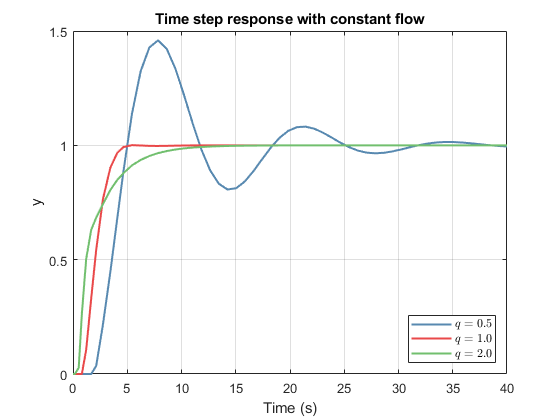

out = sim("Simulink\simulink_ex5.slx");
plot_ex5_simulink

**Figura 14: **Resposta ao degrau para a malha fechada para o controlador constante com $q\in \{0.5;1.0,2.0\}
$**.**

É evidente que o *overshoot* da resposta no domínio do tempo aumenta com a redução do fluxo. Um controlador que garanta uma boa performance para todos os casos de $q$ pode ser projetado de dois modos:

- Controlador de ganho constante amostrado com uma taxa inversamente proporcional a $q$;

- Controlador de ganho parametrizado em função de $q$.

A primeira abordagem foi aplicada sobre um controlador PI associado a blocos *zero-order-hold* (ZOH) amostrados à taxa $h=1/2q$. Por sua vez, a segunda abordagem foi realizada utilizando a formulação de Ziegler-Nichols, para o qual os ganhos de um controlador PI para o processo $G_0$ são determinados como:

$K_c = \frac{0.9T}{\tau}$ e $T_i = 0.3\tau$

Na Fig. 15 estão apresentadas as respostas ao degrau unitário utilizando a segunda abordagem descrita.

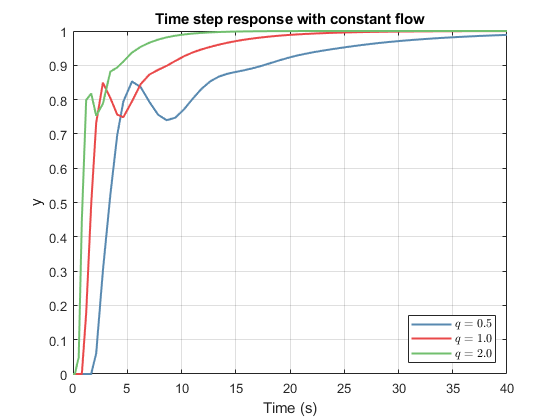

plot_ex5_simulink2;

**Figura 15: **Resposta ao degrau para a malha fechada para o controlador adaptativo para$q\in \{0.5;1.0,2.0\}
$**.**

Observando a Fig. 15, fica claro que o controlador otimizado para cada caso de teste garante a performance da malha fechada com um menor *overshoot* que o controlador constante apresentado na Fig. 14. 

Este exemplo demonstra como a atualização dos parâmetros do controlador conforme a condição de operação atual da planta $q\in \{0.5;1.0,2.0\}
$ garante a performance ótima da malha fechada. Essa estratégia de ajuste de ganho do controlador é nomeada escalonamento de ganho. Tendo em vista a necessidade do ponto de operação da planta, o GS não é adequado para processos variáveis não observáveis ou cujo modelo não é expresso em termo dos parâmetros variados.

#### **Exemplo 6:** Controle de dinâmica de uma aeronave

Esse exercício objetiva demonstrar a estratégia de escalonamento de ganho, a qual consiste na mudança dos ganhos do controlador conforme a mudança do ponto de operação do modelo. O modelo de uma aeronave de asa fixa e corpo rígido é dado por:


$$\frac{\textrm{dx}}{\textrm{dt}}=\left\lbrack \begin{array}{ccc}
a_{11}  & a_{12}  & a_{13} \\
a_{21}  & a_{22}  & a_{23} \\
0 & 0 & -a
\end{array}\right\rbrack x+\left\lbrack \begin{array}{c}
b_1 \\
0\\
a
\end{array}\right\rbrack u$$


para $x^T =\left\lbrack \begin{array}{ccc}
N_z  & \theta^{\ldotp }  & \delta_e 
\end{array}\right\rbrack$, sendo $N_z$ a aceleração normal, $\dot{\theta}$ a aceleração de *pitch* e $\delta_e$ o ângulo de elevação (conforme ilustrado na Fig 1.12 de [1]). Esse sistema possui três autovalores: $-a=-14$, $\lambda_1$ e $\lambda_2$, porém apenas $\lambda_1$ e $\lambda_2$ dependem das condições de voo. Essas condições de voo são determinadas pela altitude e número de March, conforme a Tabela 1.1 de [1]. Na Fig. 16 estão ilustradas as respostas ao degrau para um mesmo controlador de ganho constante nas quatro condições de operação definidas na a Tabela 1.1 de [1].

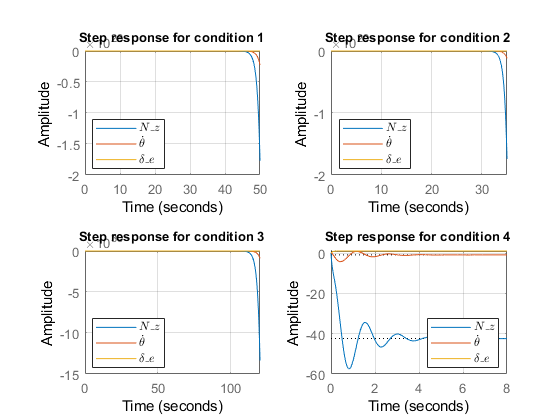

plot_ex6

**Figura 16: **Resposta ao degrau para um mesmo controlador constante nas quatro condições de operação da aeronave de asa fixa**.**

Observando a Fig. 16, é evidente que, para um controlador de ganho constante, esse sistema é instável para velocidades subsônicas e pouco amortecido para condições supersônicas. Dessa forma, com o intuito de garantir a estabilidade do sistema em qualquer velocidade, o controlador deve ser alterado para cada condição de operação.

Conforme o Capítulo 9 de [1], o ganho $K_{QD}$ de controle do ângulo de *pitch* pode ser agendado conforme a expressão:


$$K_{QD} = K_{AS} + (K_S - K_{AS})MF$$


para  $K_{AS}$ uma função da velocidade e $K_S$ função da altitude. A variável $MF$ é determinada por $MF = K_{MF}/(s+1)$, para $K_{MF}$ uma função do número de March.

#### **Exemplo 7 e 8:** Rejeição de um distúrbio regular no processo

Esses exercícios tem por exemplo exemplificar um controlador que rejeite uma perturbação. Se essa perturbação possuir regularidade em frequência, é possível criar um controlador que filtre essa característica exclusiva do distúrbio. 

Uma aplicação dessa estratégia de controle é o piloto automático de um navio. Esse controlador deve compensar as forças do vento, ondas e correntes marítimas na velocidade do navio. Considerando que essas condições não são constantes no tempo, o sistema deve identificar as características atuais do distúrbio e adaptar.

Foram realizados três experimentos com o diagrama apresentado na Fig. 17. O distúrbio adicionado ao processo é gerado ao filtrar um ruído branco por um passa-faixa centrado em $\omega$. Essa frequência será rejeitada pelo controlador, o qual possui um alto ganho na frequência central $\omega_e$. Idealmente, $\omega_e=\omega$. 

A dinâmica da planta foi mantida constante, enquanto as frequências centrais do controlador e ruído foram alteradas para $0.1$ e $0.05$rad/s. As respostas à referência nula para cada caso de teste estão ilustradas na Fig. 18.

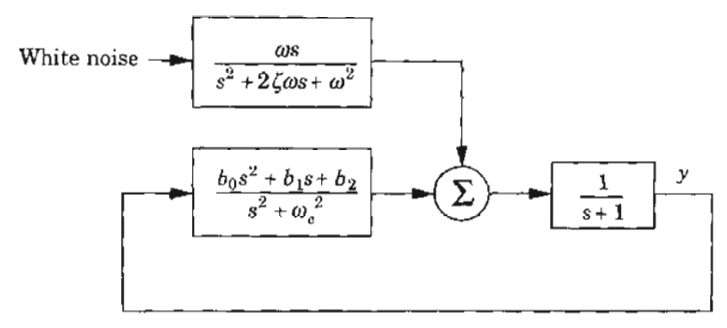

**Figura 17: **Diagrama proposto para o exercício proposto 8 [1]**.**

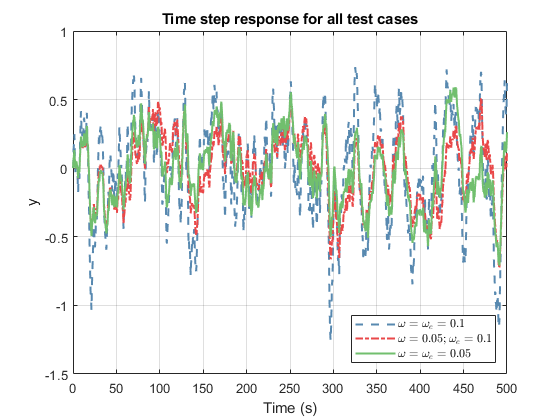

out = sim("Simulink\simulink_ex8.slx");
plot_ex8_simulink

**Figura 18: **Resposta à referência nula para $\omega=\omega_{e}=0.1$, $$\omega=0.05$ e $\omega_{e}=0.1$, e$\omega=\omega_{e}=0.05
$.

Conforme a lógica supracitada, o erro deveria ser mínimo para $\omega=\omega_e$. Entretanto, observando a Fig. 18, é evidente que o erro para $\omega=\omega_{e}=0.1$ é maior do que para o caso $$\omega=0.05$ e $\omega_{e}=0.1$. Essa diferença é justificada pelo ganho da função de transferência do filtro passa-faixa, a qual é proporcional a $\omega$. Dessa forma, para uma comparação justa entre os laços, é necessário ajustar a magnitude do ruído filtrado.

Analogamente, a magnitude do erro é maior para o caso $\omega=\omega_{e}=0.1$ do que para $\omega=\omega_{e}=0.05$. Como o controlador é projetado conforme a frequência $\omega_e$, o ganho para a função de transferência de sensibilidade em malha fechada para $\omega=\omega_{e}=0.1$ é maior que para $\omega=\omega_{e}=0.05$. Logo, os resultados obtidos não podem ser comparados.

#### **Exemplo 9 e 10:** Controle adaptativo linear

Em um sistema SISO (*single input, single output*) de um processo linear, o controlador adaptativo pode ser representado por:


$$v = -Lx$$


para $L$ uma matriz parametrizável. De modo geral, $x = f(y,u_c)$, para $y$ a saída do sistema em malha fechada e $u_c$ o valor de referência. Dessa forma, a função de transferência generalizada de um controlador linear adaptativo é:


$$R(s)U(s) = -S(s)Y(s)+T(s)U_c(s)$$


para $R(s)$, $S(s)$, $T(s)$ polinômios. 

#### **Exemplo 11, 12 e 13:** Controle adaptativo não linear

A parametrização de um controlador não-linear pode ser realizada por GS, MRAS, STR ou uma abordagem estocástica, como apresentada na Seção 1. Outra forma de compensar a não linearidade do processo é adicionar uma função anterior ou posterior ao controlador, como exemplificado no Ex.4. Essas estratégias de controle são mais complexas que uma lei de ganho constante, porém garantem a estabilidade em processos variáveis.

Por exemplo, em um sistema de controle de velocidade de um motor, é necessário considerar a influência do atrito. Essa força de perturbação é compensada adicionando um sinal pré-definido $u_{fc}$ à saída do controlador:


$$u_{fc} = \begin{cases} u_+, v>0\\
u_-, v<0
\end{cases}$$


para $v$ a velocidade de rotação do motor. Como a força de fricção não é simétrica nos dois sentidos de giro, são necessários dois parâmetros ($u_+$ e $u_-$) para atingir a melhor configuração do controlador. Uma solução adequada ao problema é encontrar um método de busca de parâmetros automático conforme um modelo de referência, como método dos mínimos quadrados ou algoritmo genético.

É evidente que  o método de controle adaptativo possui melhor resultados em sistemas especialistas do que leis de controle generalizadas, uma vez que os parâmetros são otimos para cada condição de operação. A título de exemplo, um piloto-automático que já possui a performance adequada ao modelo de referência pré-definido pode ser otimizado com a adição de parâmetros voltados a minimização do consumo de combustível. 

Devido à essa capacidade de adequação ao processo, os controladores adaptativos possuem uma estrutura geral a qual deve ser personalizada a cada aplicação. O produto que derivou desse conceito foi o *Novatune*, um controlador de uso geral composto por PIs e PIDs em cascata com filtros e lógica sequencial.

### Questões propostas

#### Questão 1: Caracterize o uso do termo "adaptativo" e "aprendizado" em diferentes temas.

O termo "adaptativo" se refere ao que é resultado de uma adaptação para melhor adequar-se as normas. Por exemplo, os esportes olímpicos foram adaptados para a competição paraolimpíca. Por sua vez, os exercícios resolvidos anteriormente discutidos parametrizam uma lei de controle pré-definida conforme o processo não-linear ou variável em questão. 

Por sua vez, o termo "aprendizado" representa o que é resultado de um acúmulo de experiências. Por exemplo, uma habilidade pode ser adquirida (aprendida) por meio da prática constante do ato. Por outro lado, uma nova lei de controle é aprendida após testar inúmeros casos de entrada e saída da malha e, então, prever a saída de uma entrada arbitrária. 

Sendo assim, no campo de robótica e automação, adaptativo e aprendizado são técnicas semelhantes, porém diferentes no aspecto da forma (formulação) da lei de controle.

#### **Questão 2: Descreva o controle adaptativo de alguns fabricantes.**

Na área de automação, a SIEMENS desenvolveu um controle adaptativo para uma máquina de corte de ferro, aço e titânio [2]. Tendo em vista a diferença de dureza entre os materiais, a velocidade da serra de corte deve ser variada conforme o substrato. O controlador implementado monitora a carga sobre a serra e reduz a velocidade de corte em caso de sobrecarga. Essa observação dispensa a consideração do pior caso de material de corte. Dessa forma, a linha de produção é otimizada para atender a velocidade de corte ideal para cada material. 

Por sua vez, na área da robótica, a Embention desenvolveu um drone para *picking* com controle adaptativo [3]. O algoritmo de piloto automático desse robô altera os parâmetros do controlador em voo conforme a mudança do modelo de referência $-$ i.e. a força exercida por uma carga sobre o corpo do drone. Essa força varia segundo o peso da carga e comprimento do cabo que conecta essa ao drone. A mesma estratégia de adaptação do controlador em tempo de voo foi aplicada para [4] e [5]. Uma vez que o modelo de referência é modificado quando o drone rasteja ou modifica a angulação de suas hastes, a condição de operação é alterada. Por sua vez, essa alteração reflete nos parâmetros do controlador.

#### **Questão 3: Quais fatores são úteis para a escolha de um controle adaptativo? Cite exemplo de situações que o controle adaptativo é útil.**

Um controlador adaptativo, por ser não linear, é mais complexo que um controle de ganho fixo. Dessa forma, é importante investigar o processo estudado e atestar a necessidade de uma realimentação de ganho variável.

O primeiro caso representa um o processo constante e sem adição de perturbação. Caso o modelo da planta seja conhecido, esse é o experimento é considerado o padrão ideal no estudo de controladores. Nessa situação, é possível estabilizar a malha fechada com um controlador de ação P, I e/ou D com ganho constante.

O segundo caso representa um processo variável e sem adição de perturbação. Nesse experimento, compara-se a saída do processo com o modelo de referência para determinar a condição de operação atual da planta. Conforme essa condição de operação, os ganhos do controlador são atualizados para garantir a performance adequada. Essa estratégia de controle é denominada escalonamento de ganho e é apenas apropriada para uma planta com modelo disponível. Caso o modelo do processo seja desconhecido, deve-se incluir no laço de realimentação um estimador dos estados do processo $-$e.g.  STR, filtro de Kalman e de partículas $-$ e usar uma lei de controle não-linear adaptativa atualizada a cada passo de cálculo. 

O terceiro caso é composto por um processo variável com adição de perturbação. Caso o modelo desse distúrbio seja conhecido, é possível adicionar, ao controlador, um filtro. Esse filtro rejeita as componentes de frequência característica da perturbação. Por outro lado, caso o distúrbio seja desconhecido, pode-se adicionar ao controlador uma ação integral. Em ambas as situações, deve-se ainda aplicar escalonamento de ganho ou controle adaptativo, tendo em vista o processo variável.

#### **Questão 4: Faça uma revisão bibliográfica do campo de controle adaptativo e enumere os métodos, teoria e aplicações.**

Essa revisão bibliográfica poderá ser incrementada utilizando artigos atualizados. Porém, para simplificar o exercício, considera-se a teoria apresentada na Seção 1.

#### **Questão 5: Válvula não linear**

A linearização do sistema proposto está descrita no Ex.4. Com o bloco inversor da não linearidade, as raízes para a equação característica de malha fechada são:

s = tf('s');
G0 = 1/(s+1)^3;
H = 0.15*(1 + 1/s);
[~,P] = tfdata(G0*H/(1+G0*H),'v');
roots_P = roots(P)

roots_P =    0.0000 + 0.0000i
  -1.3352 + 0.0000i
  -1.0004 + 0.0000i
  -1.0000 + 0.0004i
  -1.0000 - 0.0004i
  -0.9996 + 0.0000i
  -0.3324 + 0.0430i
  -0.3324 - 0.0430i


Dessa forma, é evidente que todas as raízes do polinômio característico de malha fechada possuem parte real negativa. Logo, o sistema é considerado estável. 

#### **Questão 6: Controle de concentração do tanque**

A solução para essa questão está descrita no Ex. 5. Para o processo


$$G_0(s) = \frac{e^{s\tau}}{1+sT}$$


e utilizando a formulação de Ziegler-Nichols, os ganhos de um controlador PI adequado são determinados por:

$K_c = \frac{0.9T}{\tau}$ e $T_i = 0.3\tau$

Assim sendo, os ganhos do controlador PI ideal para $q=0.5$,$1$ e $2$ são:

q = [0.5 1 2];
T = 1./q; tau = T;
Kc = 0.9*T/tau

Kc = 0.9000

Ti = 0.3*tau

Ti =     0.6000    0.3000    0.1500


Fica evidente que o ganho proporcional é constante para qualquer valor de fluxo $q$, uma vez que $V_m=V_d=1$. Já o ganho integral $K_i=1/Ti$ é diretamente proporcional ao fluxo $q$. Os resultados da resposta ao degrau estão ilustrados na Fig. 15.

Os controladores adaptados para cada condição de teste ($q\in \{0.5;1.0,2.0\}
$) foram aplicados sobre o processo $G_0$ com $q=1$. A resposta ao degrau para cada caso está ilustrada na Fig. 19.

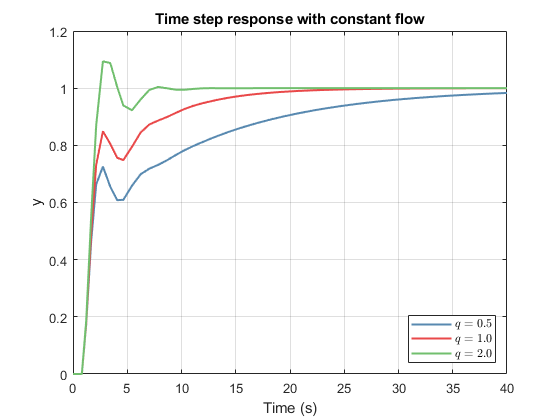

out = sim("Simulink\simulink_ex5.slx");
plot_ex5_simulink3

**Figura 19: **Resposta ao degrau para a malha fechada para o controlador adaptativo para$q\in \{0.5;1.0,2.0\}
$ considerando o processo para o fluxo nominal $q=1$**.**

Comparando a Fig. 15 e Fig. 19, é evidente o *overshoot* para o controlador projetado com $q=2$. Esse fato é justificado pelo ganho integral $K_i$, uma vez que é menor para $q=1$ que para $q=2$. Em outros termos, a observação procede da maior rejeição à perturbação é quanto mais veloz o fluxo estiver no duto de entrada.

Esse exercício evidencia que a performance ótima é alcançada quando o controlador é adaptado conforme o processo em execução. Portanto, o comportamento dos sistemas cujo ponto de operação diferem da condição empregada para o ajuste dos ganhos é sub-ótima.

#### **Questão 7: Realimentação proporcional**

Esse exercício é semelhante ao Ex. 6. O sistema em estudo possuí duas entradas e duas saídas:


$$\begin{array}{l}
\frac{\textrm{dx}}{\textrm{dt}}=\left\lbrack \begin{array}{ccc}
-1 & 0 & 0\\
0 & -3 & 0\\
0 & 0 & -1
\end{array}\right\rbrack x+\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 2\\
0 & 1
\end{array}\right\rbrack u\\
\;\;y=\left\lbrack \begin{array}{ccc}
1 & 1 & 0\\
1 & 0 & 1
\end{array}\right\rbrack x
\end{array}$$


Um laço de realimentação foi adicionado entre a segunda entrada e a segunda saída, ou, seja: $u_2=-k_2y_2$. O novo sistema pode ser então representado por:


$$\frac{\textrm{dx}}{\textrm{dt}}=\left\lbrack \begin{array}{ccc}
-1 & 0 & 0\\
-2k_2  & -3 & -2k_2 \\
-k_2  & 0 & -1-k_2 
\end{array}\right\rbrack x+\left\lbrack \begin{array}{c}
1\\
0\\
0
\end{array}\right\rbrack u$$


A função de transferência $Y_1 \left(s\right)/U_1 \left(s\right)$ é representada por:

H = simplifyFraction(solve_q6());
H(1)

$$ans = \frac{k_{2}+4\,s-k_{2}\,s+s^{2}+3}{\left(s+1\right)\,\left(s+3\right)\,\left(k_{2}+s+1\right)}$$

Logo, é evidente que $k_2$ determina um dos polos da malha fechada. Para o regime permanente, conforme o teorema do valor final, tem-se;


$$\lim_{t\rightarrow 0} y_1(t) = \lim_{s\rightarrow0}s\frac{s^2+(4-k_2)s+3+k_2}{(s+1)(s+3)(s+1+k_2)}$$


Caso $k_2=-1$:


$$ \lim_{s\rightarrow0}s\frac{s^2+(4-k_2)s+3+k_2}{(s+1)(s+3)(s+1+k_2)}=\lim_{s\rightarrow0}\frac{s^2+(4-k_2)s+3+k_2}{(s+1)(s+3)} = \frac{2}{3}$$


Por sua vez, caso $k_2\neq-1$:


$$ \lim_{s\rightarrow0}s\frac{s^2+(4-k_2)s+3+k_2}{(s+1)(s+3)(s+1+k_2)} = \frac{0}{3(1+k_2)} = 0$$


Dessa forma, $k_2$ determina o erro em regime permanente da entrada $u_1$ na saída $y_1$.

Na Fig.20, 21 e 22 estão ilustradas as respostas ao degrau para as saídas $y_1$ e $y_2$ considerando três experimentos $k_2=-1$,$$k_2=-0.5$
$ e $k_2 = -2$. No primeiro caso, há um polo nulo e o sistema é marginalmente estável. No segundo caso, todos os polos são negativos. Por fim, no último caso, há pelo menos um polo no semi-plano direito e o sistema é instável.

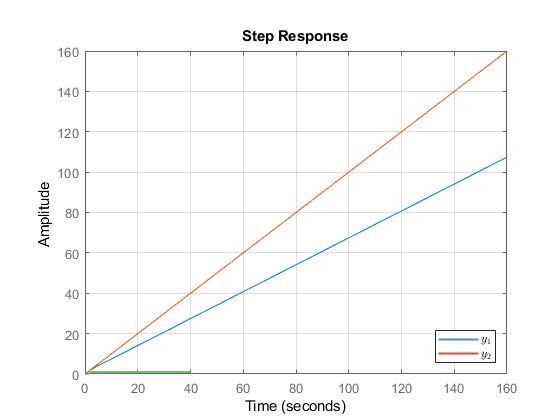

solve_q6_plot
step(h1(1)), hold on;
step(h2(1)), grid, hold off;
legend("$y_{1}$","$y_{2}$", "Interpreter", "Latex")

**Figura 20: **Resposta ao degrau para a malha fechada de saída $y_1$ e $y_2$ para $k_2=-1$**.**

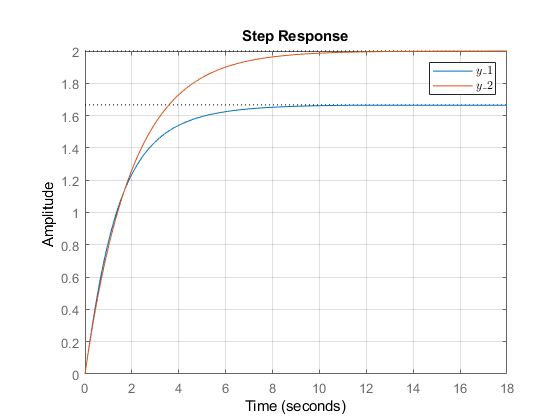

figure()
step(h1(2)), hold on;
step(h2(2)), grid, hold off;
legend("$y_{1}$","$y_{2}$", "Interpreter", "Latex")

**Figura 21: **Resposta ao degrau para a malha fechada de saída $y_1$ e $y_2$ para $k_2=-0.5$**.**

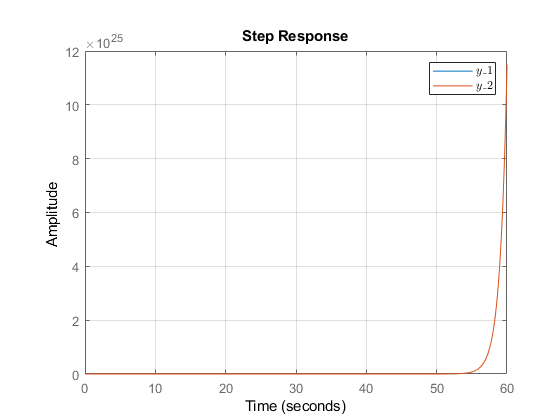

figure()
step(h1(3)), hold on;
step(h2(3)), grid, hold off;
legend("$y_{1}$","$y_{2}$", "Interpreter", "Latex")

**Figura 22: **Resposta ao degrau para a malha fechada de saída $y_1$ e $y_2$ para $k_2=-2.0$**.**

Com base nos experimentos realizados, fica claro que a lei de controle proporcional é suficiente para estabilizar a malha fechada desde que $k_p$ produza polos com parte real negativa.

#### Questão 8: Processo não linear

Essa questão tem por objetivo analisar a variação dos parâmetros referentes à não linearidade do processo em relação à resposta ao degrau do sistema em malha fechada. O diagrama de blocos simulado foi equivalente a Fig 1.25 de [1]. 

O sistema exemplificado representa uma máquina de corte de metal, cuja variável de controle é a força aplicada sobre a placa. Essa força $F$ é aproximada por:


$$F = ka\Big(\frac{v}{N}\Big)^\alpha$$


para $v$ a velocidade do sinal de alimentação, $N$ a velocidade da engrenagem, $a$ a profundidade do corte, $\alpha\in[0.5,1]$ e $k$ um valor positivo. 

Os valores nominais adotados foram $\alpha=0.7$, $k=1$, $a = 1$, $\zeta =0\ldotp 7$ e $\omega = 5$. O ganho integral do controlador foi definido $T_i=1$. Em seguida, foram realizados dois experimentos: no primeiro, variou-se $N$ de 0.2, 1 e 2; no segundo experimento, variou-se $a$ de 0.5, 1 e 4. As respostas ao degrau para os dois experimentos estão ilustradas na Fig. 23 e Fig.24, respectivamente.

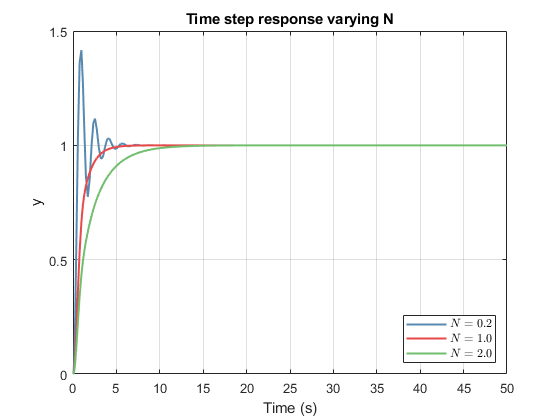

out = sim("Simulink\simulink_q8.slx");
solve_q8_plot

**Figura 23: **Resposta ao degrau para a malha fechada para $N\in \{0.2;1.0,2.0\}
$**.**

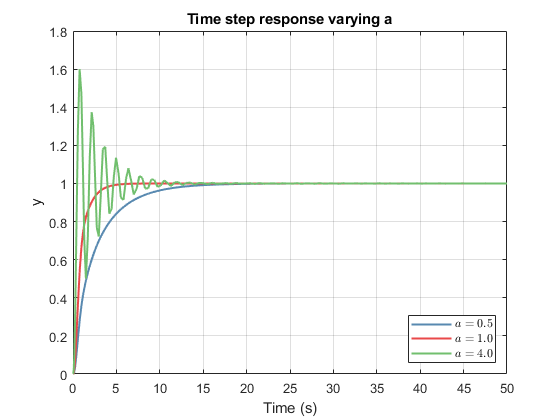

solve_q8_plot2

**Figura 24: **Resposta ao degrau para a malha fechada para $a\in \{0.5;1.0,4.0\}
$**.**

Observando a Fig. 23 e a expressão da força $F$, é evidente que a saída da malha fechada é inversamente proporcional à velocidade $N$. Assim sendo, quanto menor $N$, maior a força $F$ e, portanto, maior *overshoot* da resposta ao degrau. Por sua vez, observando a Fig.24 e a expressão de $F$, é claro que a saída da malha fechada é diretamente proporcional a $a$. Dessa forma, quanto menor $\alpha$, menor a força $F$ e, portanto, menor *overshoot* da resposta ao degrau.

No caso dessa questão, um escalonamento de ganho poderia ser aplicado conforme as mudanças nos parâmetros de $F$ para garantir o mínimo *overshoot*. Tendo em vista que a função não linear é conhecida, não há necessidade da aplicação de métodos de previsão de modelo (e.g. MRAS e STR).

#### Questão 9: Processo de primeira ordem variável

Nessa questão, o processo em estudo é variável. Sendo o controlador constante, será analisada a sensibilidade do sistema de malha aberta às mudanças do processo $G_0$ representado por:


$$G_0 = \frac{K}{s+a}$$


para $K = 1+\Delta K$ e $a = 1+\Delta a$. Foi adotado que $-0.5 \leq \Delta K \leq 2.0$ e $-2 \leq \Delta a \leq 2.0$. O primeiro experimento consiste em simular a resposta em malha aberta para diferentes valores de  $K$ e $a$. Como $a\leq0$ para $\Delta a \leq -1$, adotou-se o intervalo $K\in[0.5,3]$ e $a\in(0,3]$. As respostas ao degrau estão ilustradas na Fig. 25.

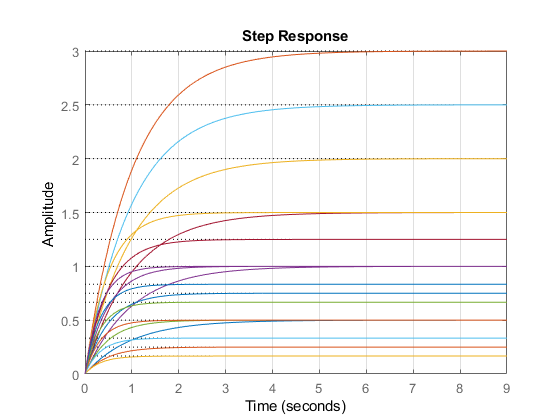

solve_q9_plot

**Figura 25: **Resposta ao degrau para a malha aberta considerando $K\in[0.5,3]$ e $a\in(0,3]$**.**

Para valores de $a\leq0$ há um polo nulo ou no semi-plano direito e, portanto, o sistema é instável. Dessa forma, o processo, mesmo que estável na condição nominal ($a=1$), pode não ser estável em malha aberta devido à incerteza $\Delta a$. 

Para o sistema nominal, um controlador proporcional $K_p=1$é suficiente para fechar a malha. A função de transferência em malha fechada é então:


$$G_{MF} = \frac{K_0}{s+ (a_0+K)} = \frac{1}{s+ 2} $$


Esse sistema possui um polo no semi-plano esquerdo e, conforme ilustrado na Fig. 26, é estável em malha fechada.

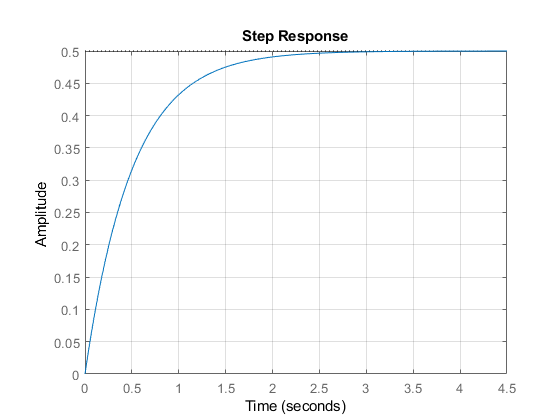

solve_q9_plot2

**Figura 26: **Resposta ao degrau para a malha fechada para o processo nominal e o controlador proporcional**.**

Esse controlador, entretanto, não é capaz de rejeitar às incertezas $\Delta a$ e $\Delta K
$, uma vez que há pelo menos uma combinação ($$\Delta a=-1$$ e $$\Delta K=-0.5$$) resultante em um polo positivo em malha fechada. As variações do processo só são rejeitadas na malha fechada nominal utilizando um controlador I, uma vez que a função de transferência é determinada por:


$$G_{MF} = \frac{K}{s^2+ as+K}$$


cujos polos $\frac{-a\pm\sqrt{a^2-4K}}{2}$ possuem parte real negativa para qualquer valor de $-0.5 \leq \Delta K \leq 2.0$ e $-2 \leq \Delta a \leq 2.0$. 

Considerando que seja adicionado um distúrbio $d(t)$ à malha no formato:


$$d(t) = \begin{cases}
-1 \;,\; 0\leq t < 6\\
2\;,\; 6\leq t < 15\\
1\;,\; 15\leq t \\
\end{cases}$$


Logo, a função de sensibilidade para a malha fechada nominal com o controlador P à rejeição desse distúrbio é:


$$S_P = \frac{s+a_0}{s+(a_0+K_0)}$$


Observando a aplicação de $d(t)$ sobre a função de transferência $S_p$ ilustrada na Fig. 27, é claro que o sistema não consegue rejeitar o distúrbio quando com controlador P. Para a ação de controle integral e o sistema nominal, é possível rejeitar a perturbação, uma vez que a função de sensibilidade resulta em


$$S_P = \frac{s(s+a_0)}{s^2+a_0s+K_0}$$


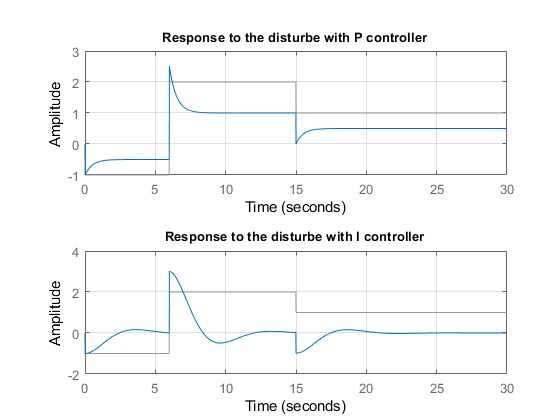

solve_q9_plot3

**Figura 27: **Sensibilidade ao distúrbio $d(t)$ para o controlador P (acima) e I (abaixo)**.**

A resposta ao distúrbio $d(t)$ utilizando o controlador I e a os parâmetros nominais $K_0$ e $a_0$ está ilustrada na Fig. 27. Observando que o valor em regime permanente $d(t)$ é nulo, é possível afirmar a rejeição da perturbação para o sistema nominal em malha fechada. Caso sejam consideradas as incertezas $\Delta a$ e $\Delta K$, é necessário aumentar um polo à função de transferência de malha fechada.

Por fim, considera-se a adição de um erro de medição $e(t)$ ao laço de realimentação. Esse erro foi representado por um ruído branco. Para esse experimento, considerou-se o processo nominal e o controlador de ação integral. Observando a resposta ao degrau ilustrado na Fig. 28, é claro que o controlador integral foi suficiente na rejeição do erro adicionado à malha fechada em regime permanente. Os picos em 6 e 15 segundos são provocados pela mudança do distúrbio $d(t)$, conforme ilustração Fig. 27. Caso sejam consideradas as incertezas $\Delta a$ e $\Delta K$, é necessário aumentar um polo à função de transferência de malha fechada.

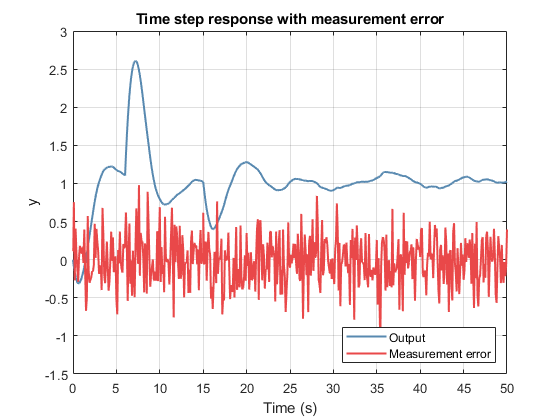

out = sim("Simulink\simulink_q9.slx");
solve_q9_simulink

**Figura 28: **Resposta ao degrau unitário para a malha fechada com o processo nominal, lei de controle integral e adição de erro de medição**.**

#### Questão 10: Processo de primeira ordem variável

Nessa questão, o processo em estudo também é variável. Sendo o controlador constante, será analisada a sensibilidade do sistema de malha aberta às mudanças do processo $G_0$ representado por:


$$G_0 = \frac{K}{s^2+a_1s+a_2}$$


para $K = 1+\Delta K$, $a_1 = 1.4+\Delta a_1$ e $a_2 = 1+\Delta a_2$. Foi adotado que $-0.5 \leq \Delta K \leq 2.0$,  $-2 \leq \Delta a_1 \leq 2.0$ e $-3 \leq \Delta a_2 \leq 3.0$. O primeiro experimento consiste em simular a resposta em malha aberta para diferentes valores de  $K$, $a_1$ e $a_2$. As respostas ao degrau para $G_0$ tal que os polos $\frac{-a_1\pm\sqrt{a_1^2-4a_2}}{2}$ sejam negativos estão ilustradas na Fig. 29.

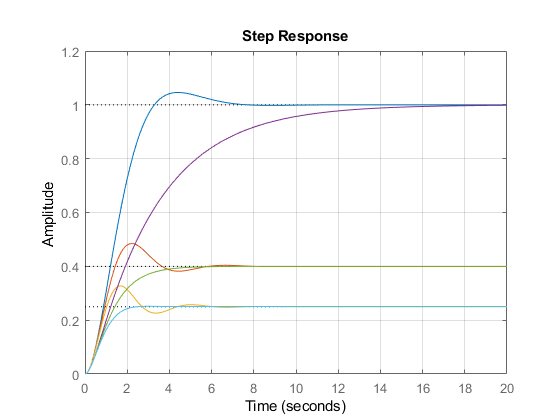

solve_q10_plot

**Figura 29: **Resposta ao degrau para a malha aberta considerando apenas os polos no semi-plano esquerdo de `s`**.**

Entretanto, há pares de valores para $\Delta a_1$ e $\Delta a_2$ que resultam em polos nulos ou positivos. Dessa forma, o processo, mesmo que estável na condição nominal, pode não ser estável em manha aberta devido às incertezas $\Delta a_1$ e $\Delta a_2$. 

Para o sistema nominal, um controlador proporcional $K_p=1$é suficiente para estabilizar a malha fechada. A função de transferência em malha fechada é então:


$$G_{MF} = \frac{K_0}{s^2 + a_{1_0}s + a_{2_0} + K_0} = \frac{1}{s^2 + 1.4s + 2} $$


Esse sistema possui dois polos no semi-plano esquerdo e, conforme ilustrado na Fig. 30, é estável em malha fechada.

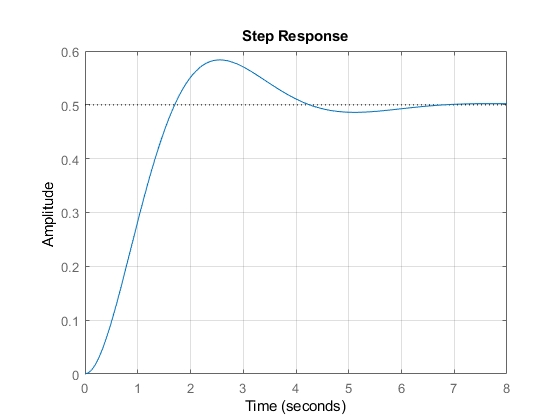

solve_q10_plot2

**Figura 30: **Resposta ao degrau para a malha fechada para o processo nominal e o controlador proporcional**.**

Esse controlador, entretanto, não é capaz de rejeitar às incertezas $\Delta a_1$,$\Delta a_2$ e $\Delta K
$, uma vez que há pelo menos uma combinação de variações que resultam em um polo com parte real positiva em malha fechada. As variações do processo só são rejeitadas para a malha fechada nominal utilizando um controlador I, uma vez que a função de transferência é determinada por:


$$G_{MF} =  \frac{K}{s^3 + a_1s^2 + a_2s + K} $$


cujos polos possuem parte real negativa para qualquer valor de $-0.5 \leq \Delta K \leq 2.0$,  $-2 \leq \Delta a_1 \leq 2.0$ e $-3 \leq \Delta a_2 \leq 3.0$. 

Considerando que seja adicionado um distúrbio $d(t)$ à malha no formato:


$$d(t) = \begin{cases}
-1 \;,\; 0\leq t < 6\\
2\;,\; 6\leq t < 15\\
1\;,\; 15\leq t \\
\end{cases}$$


Logo, a função de sensibilidade para a malha fechada nominal com o controlador P à rejeição desse distúrbio é:


$$S_P = \frac{s^2 + a_{1_0}s + a_{2_0}}{s^2 + a_{1_0}s + a_{2_0} + K_0}$$


Observando a aplicação de $d(t)$ sobre a função de transferência $S_p$ ilustrada na Fig. 31, é claro que o sistema possui um erro em regime permanente quando com controlador P. Para a ação de controle integral e o sistema nominal, é possível rejeitar a perturbação, uma vez que a função de sensibilidade resulta em


$$S_P = \frac{s^3 + a_1s^2 + a_2s }{s^3 + a_1s^2 + a_2s+ K}}$$


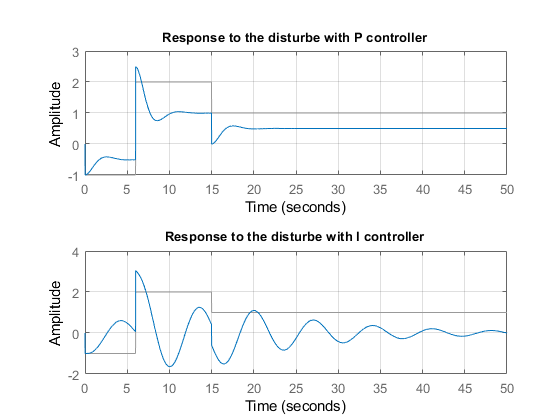

solve_q10_plot3

**Figura 31: **Sensibilidade ao distúrbio $d(t)$ para o controlador P (acima) e I (abaixo)**.**

A rejeição ao distúrbio $d(t)$ utilizando o controlador I e a os parâmetros nominais está ilustrada na  Fig. 31. Observando que o valor em regime permanente entre cada degrau de $d(t)$ é nulo, é possível afirmar a rejeição da perturbação para o sistema em malha fechada. Observando que o valor em regime permanente $d(t)$ é nulo, é possível afirmar a rejeição da perturbação para o sistema nominal em malha fechada.  Caso sejam consideradas as incertezas $\Delta a_1$,$\Delta a_2$ e $\Delta K
$, é necessário aumentar um polo à função de transferência de malha fechada.

Por fim, considera-se a adição de um erro de medição $e(t)$ ao laço de realimentação. Esse erro foi representado por um ruído branco. Para esse experimento, considerou-se o processo nominal e o controlador de ação integral. Observando a resposta ao degrau ilustrado na Fig. 32, é claro que o controlador integral foi suficiente na rejeição do erro adicionado à malha fechada. Os picos em 6 e 15 segundos são provocados pela mudança do distúrbio $d(t)$, conforme ilustração Fig. 31. Caso sejam consideradas as incertezas $\Delta a_1$,$\Delta a_2$ e $\Delta K
$, é necessário aumentar um polo à função de transferência de malha fechada.

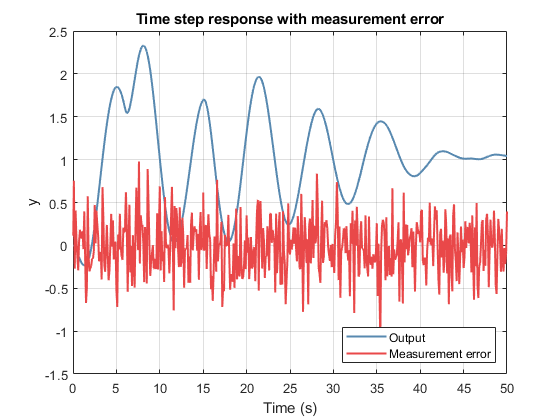

out = sim("Simulink\simulink_q10.slx");
solve_q9_simulink

**Figura 32: **Resposta ao degrau unitário para a malha fechada com o processo nominal, lei de controle integral e adição de erro de medição**.**

### Referências Bibliográficas

[1] K. ASTRÖM, B. WITTENMARK. **Adaptative Control**. Courier Corporation, 2008. ISBN 0486462781.

[2] T. RESCH. **Shorter mass production times**. Acesso em: 13 de abril, 2021. Disponível em: [https://ingenuity.siemens.com/2019/05/shorter-mass-production-times/](https://ingenuity.siemens.com/2019/05/shorter-mass-production-times/).

[3] EMBENTION INC. **Thetered UAV**. Acesso em: 13 de abril, 2021. Disponível em:[ https://www.embention.com/product/tethered-uav/](https://www.embention.com/product/tethered-uav/)

[4] D. FALANGA et. al. **The Foldable Drone: A Morphing Quadrotor that can Squeeze and Fly**. Acesso em: 13 de abril, 2021. Disponível em: [https://www.youtube.com/watch?v=jmKXCdEbF_E](https://www.youtube.com/watch?v=jmKXCdEbF_E)

[5] D. ZARROUK. **The Flying STAR robot, a hybrid flying crawling quadcopter robot**. Acesso em: 13 de abril, 2021. Disponível em: [https://www.youtube.com/watch?v=xLuQifpJv_8&pp=qAMBugMGCgJwdBAB](https://www.youtube.com/watch?v=xLuQifpJv_8&pp=qAMBugMGCgJwdBAB)